Question 1

L = 1000 ;
X = (1:L);
D = randi([0 1],L,1);       %generating a random binary sequence of length 1000

%generating a rectangular pulse S
A = 1;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end

Question 2

mean = 0 ;
var = 1 ;
N = mean + var* randn(1,L);   %generating AWGN with zero mean and variance sigma

Question 3

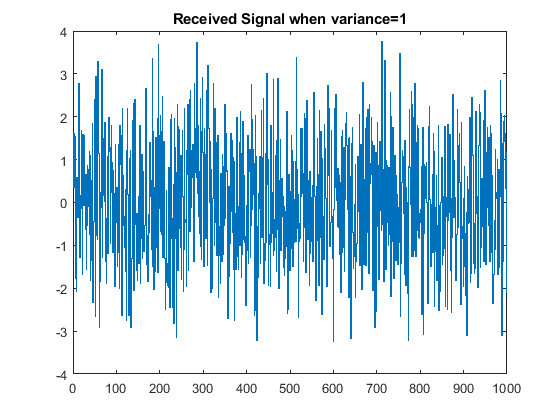

R = S + N  ;                  %generating received signal

%plotting the received signal when variance=1
figure;
stairs(X,R);
title("Received Signal when variance=1");

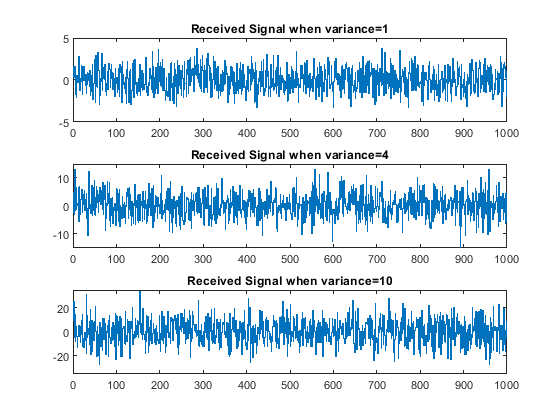

%generating the received signal when variance=4
var1 = 4 ;
N1 = mean + var1* randn(1,L);
R1 = S + N1  ; 

%generating the received signal when variance=10
var2 = 10 ;
N2 = mean + var2* randn(1,L);
R2 = S + N2 ;

%plotting the graphs
figure;
subplot(3,1,1);
stairs(X,R);
title("Received Signal when variance=1");
subplot(3,1,2);
stairs(X,R1);
ylim([-15,15]);
title("Received Signal when variance=4");
subplot(3,1,3);
stairs(X,R2);
ylim([-35,35]);
title("Received Signal when variance=10");

By oberserving the above three plots of received signal with noise variance 1,4 and 10, we can conclude that; when the variance is increased the amplitude of received signal also increases. So the signal get more distorted.

Question 4

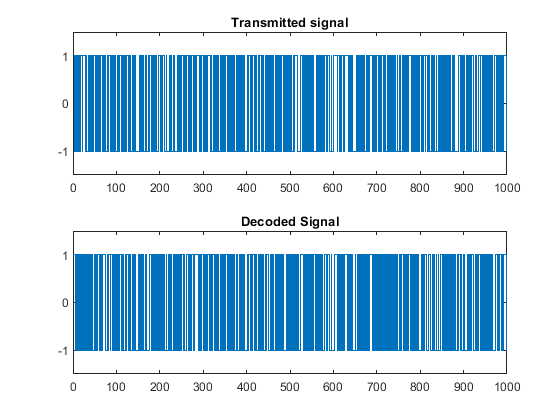

%generating the Y sequence
tau = 0;
Y = zeros(1,L) ;            %generating a zero sequence of length L
for i = 1:L 
    if R(i) <= tau 
        Y(i) = (-1)*A;      %assigning -A if R(i) is lesser than or equal to tau
    else
        Y(i) = A ;          %assigning A if R(i) is greater than tau
    end
end

%plotting the tranmitted signal
figure;
subplot(2,1,1);
stairs(X,S);
ylim([-1.5,1.5]);
title("Transmitted signal");

%plotting sequence of Y
subplot(2,1,2);
stairs(X,Y);
ylim([-1.5,1.5]);
title("Decoded Signal");

To observe the differences between sequence of Y and transmitted signal ,

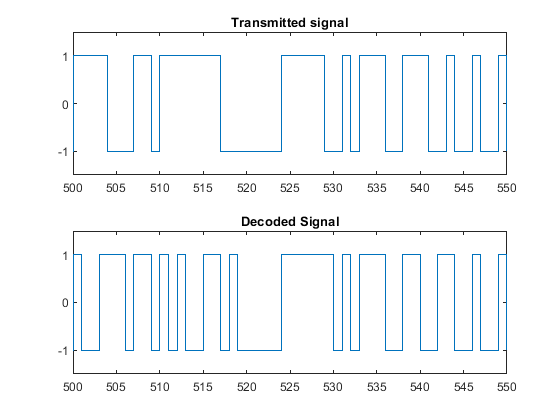

figure;
subplot(2,1,1);
stairs(X,S);
axis([500 550 -1.5 1.5]);
title("Transmitted signal");
subplot(2,1,2);
stairs(X,Y);
axis([500 550 -1.5 1.5]);
title("Decoded Signal");

According to the above two plots, there are a few number of bits which are identified incorrectly. Most of the bits in the decoded signal are same as the transmitted signal.

Question 5

Repeating the above code for L = 100000,

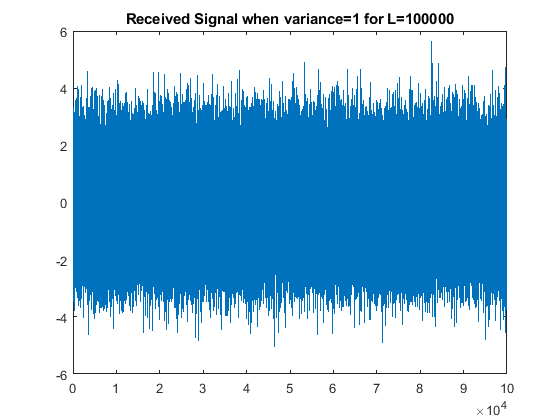

L = 100000 ;
X = (1:L);
D = randi([0 1],L,1);       %generating a random binary sequence of length 1000
A = 1;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end
mean = 0 ;
var = 1 ;
N = mean + var* randn(1,L);
R = S + N  ;                  %generating received signal
%plotting the received signal when variance=1
figure;
stairs(X,R);
title("Received Signal when variance=1 for L=100000");

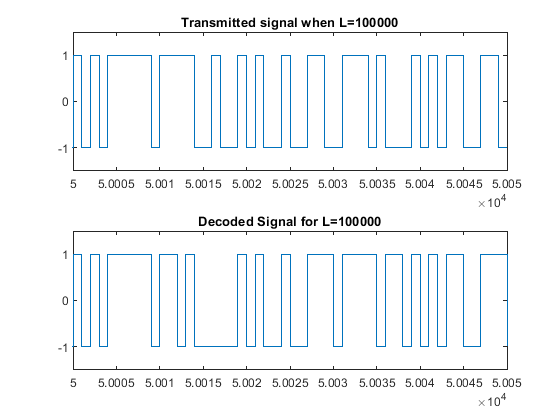

%generating the Y sequence for L = 100000
tau = 0;
Y = zeros(1,L) ;            %generating a zero sequence of length L
for i = 1:L 
    if R(i) <= tau 
        Y(i) = (-1)*A;      %assigning -A if R(i) is lesser than or equal to tau
    else
        Y(i) = A ;          %assigning A if R(i) is greater than tau
    end
end

figure;
subplot(2,1,1);
stairs(X,S);
axis([50000 50050 -1.5 1.5]);
title("Transmitted signal when L=100000");
subplot(2,1,2);
stairs(X,Y);
axis([50000 50050 -1.5 1.5]);
title("Decoded Signal for L=100000");

By comparing above two plots with the two plots for L = 1000, we can obseve higher number of bit errors when L is increased.

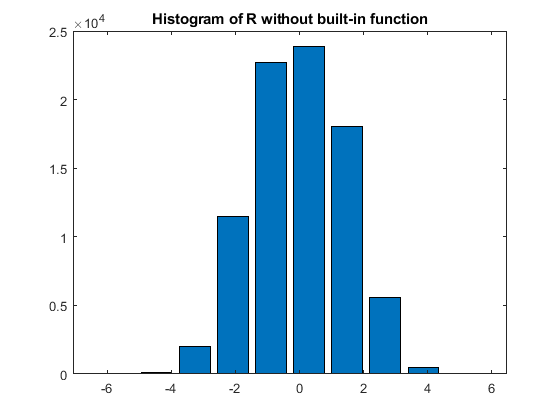

bin1 = 10;
width = (max(R)-min(R))/(bin1-1);
bins = (min(R)-width/2:width:max(R));

%calculating values for each bin
val = zeros(1,bin1);  % generating a zero sequence of length bin1
for j = 1:L 
    for k = 1:bin1
        if (R(j)>=bins(k)-width/2) && (R(j)< bins(k)+width/2)
            val(k) = val(k)+1;
        end
    end
end
val1 = val/width;

%plotting histogram without built in function
figure;
bar(bins,val1);
title("Histogram of R without built-in function");

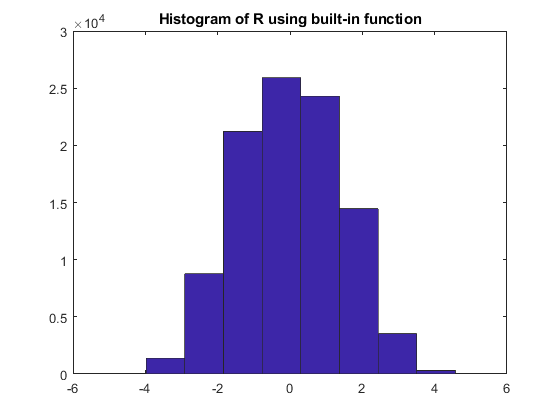

%plotting histogram using built in function
figure;
hist(R,bin1);
title("Histogram of R using built-in function");

Question 5 a) Bins =100

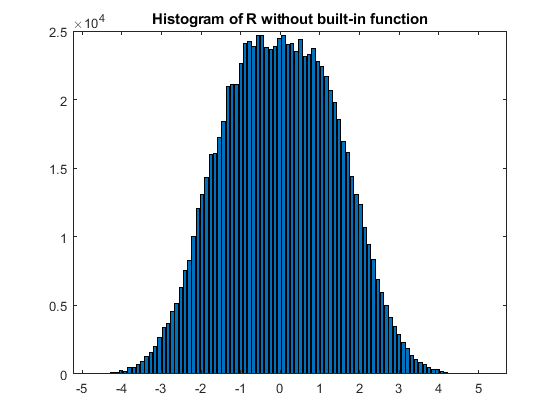

bin1 = 100;
width = (max(R)-min(R))/(bin1-1);
bins = (min(R)-width/2:width:max(R));

%calculating values for each bin
val = zeros(1,bin1);  % generating a zero sequence of length bin1
for j = 1:L 
    for k = 1:bin1
        if (R(j)>=bins(k)-width/2) && (R(j)< bins(k)+width/2)
            val(k) = val(k)+1;
        end
    end
end
val1 = val/width;

%plotting histogram without built in function
figure;
bar(bins,val1);
title("Histogram of R without built-in function");

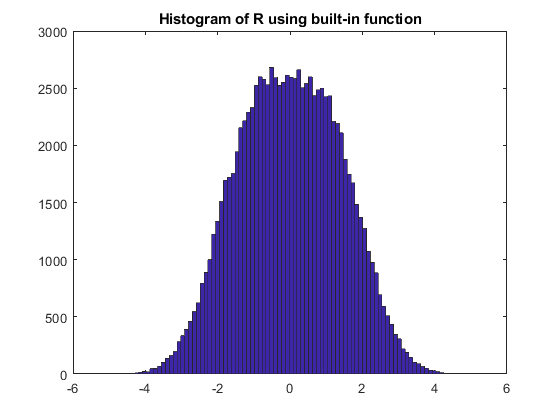

%plotting histogram using built in function
figure;
hist(R,bin1);
title("Histogram of R using built-in function");

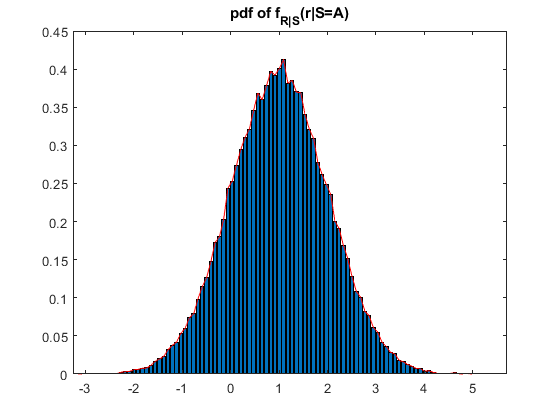


R_S1 = [];
R_S2 = [];
for l = 1:L
    if S(l) == A
        R_S1(end+1) = R(l); %taking the values of R when S = A
    else
        R_S2(end+1) = R(l); %taking the values of R when S = -A
    end
end

bin2 = 100;
width2 = (max(R_S1)-min(R_S1))/(bin2-1);
bins2 = (min(R_S1)-width2/2:width2:max(R_S1));
[y1,x1] = hist(R_S1,bins2);      %plotting the histogram
y1 = y1/((length(R_S1)-1)*width2);
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');                %plotting the pdf of f_{R|S}(r|S=A)
title("pdf of f_{R|S}(r|S=A)");

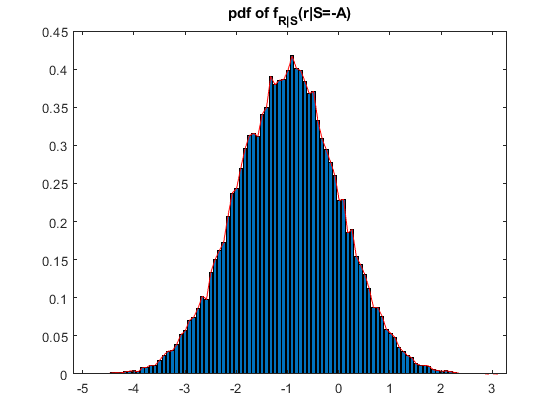


bin3 = 100;
width3 = (max(R_S2)-min(R_S2))/(bin3-1);
bins3 = (min(R_S2)-width3/2:width3:max(R_S2));
[y2,x2] = hist(R_S2,bins3);      %plotting the histogram
y2 = y2/((length(R_S2)-1)*width3);
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');                %plotting the pdf of f_{R|S}(r|S=A)
title("pdf of f_{R|S}(r|S=-A)");


%calculating E[R|S=A]
ER_SA=sum(width2.*x1.*y1)

ER_SA = 1.0039

%calculating E[R|S=-A]
ER_SA1=sum(width3.*x2.*y2)

ER_SA1 = -1.0032

%calculating E[R]
[y,x]=hist(R,bins);
y = y/(L*width);

ER=sum(width.*x.*y)

ER = -2.8058e-04

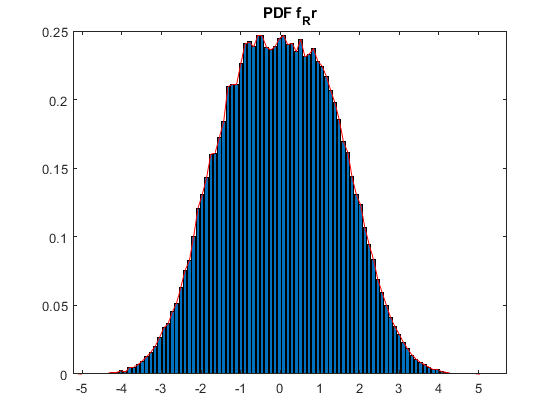

%plotting f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF f_{R}r");

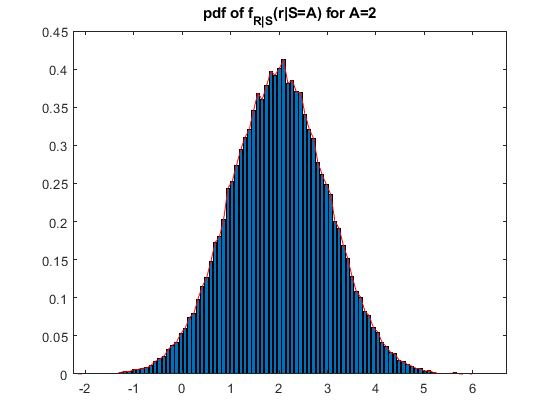

A = 2;
L = 100000 ; 
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end

R=S+N;

R_S1 = [];
R_S2 = [];
for l = 1:L
    if S(l) == A
        R_S1(end+1) = R(l);
    else
        R_S2(end+1) = R(l);
    end
end

bin2 = 100;
width2 = (max(R_S1)-min(R_S1))/(bin2-1);
bins2 = (min(R_S1)-width2/2:width2:max(R_S1));

figure;
[y1,x1] = hist(R_S1,bins2);      %plotting the histogram
y1 = y1/((length(R_S1)-1)*width2);
bar(x1,y1);
hold on;
plot(x1,y1,'r');                %plotting the pdf of f_{R|S}(r|S=A)
title("pdf of f_{R|S}(r|S=A) for A=2");

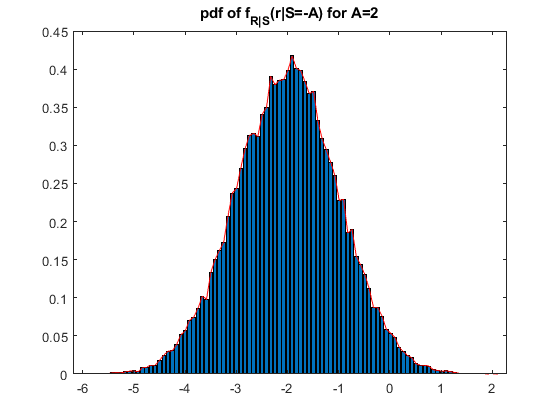


bin3 = 100;
width3 = (max(R_S2)-min(R_S2))/(bin3-1);
bins3 = (min(R_S2)-width3/2:width3:max(R_S2));

[y2,x2] = hist(R_S2,bins3);      %plotting the histogram
y2 = y2/((length(R_S2)-1)*width3);
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');                %plotting the pdf of f_{R|S}(r|S=-A)
title("pdf of f_{R|S}(r|S=-A) for A=2");

width = (max(R)-min(R))/(bin1-1);
bins = (min(R)-width/2:width:max(R));
%calculating E[R|S=A]
ER_SA=sum(width2.*x1.*y1)

ER_SA = 2.0039

%calculating E[R|S=-A]
ER_SA1=sum(width3.*x2.*y2)

ER_SA1 = -2.0032

%calculating E[R]
[y,x]=hist(R,bins);
y = y/(L*width);

ER=sum(width.*x.*y)

ER = -5.6722e-04

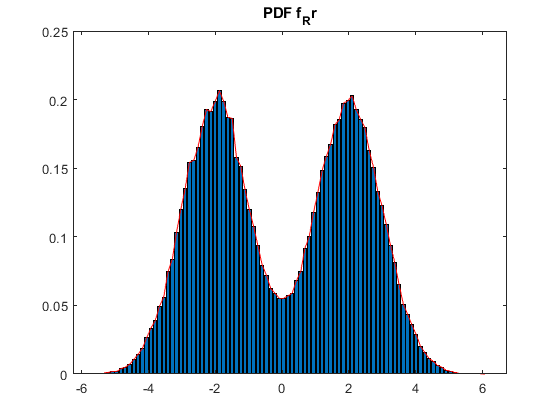

%plotting f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF f_{R}r");

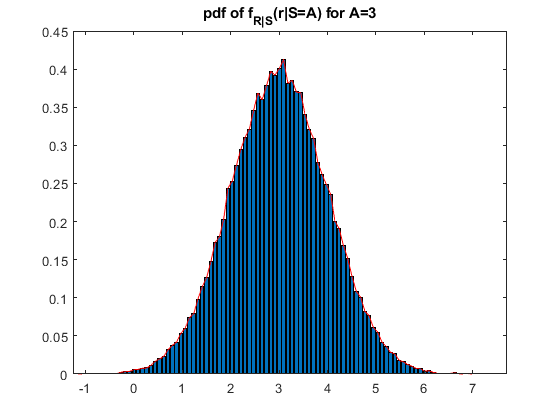

A = 3;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end

R=S+N;

R_S1 = [];
R_S2 = [];
for l = 1:L
    if S(l) == A
        R_S1(end+1) = R(l);
    else
        R_S2(end+1) = R(l);
    end
end

bin2 = 100;
width2 = (max(R_S1)-min(R_S1))/(bin2-1);
bins2 = (min(R_S1)-width2/2:width2:max(R_S1));

figure;
[y1,x1] = hist(R_S1,bins2);      %plotting the histogram
y1 = y1/((length(R_S1)-1)*width2);
bar(x1,y1);
hold on;
plot(x1,y1,'r');                %plotting the pdf of f_{R|S}(r|S=A)
title("pdf of f_{R|S}(r|S=A) for A=3");

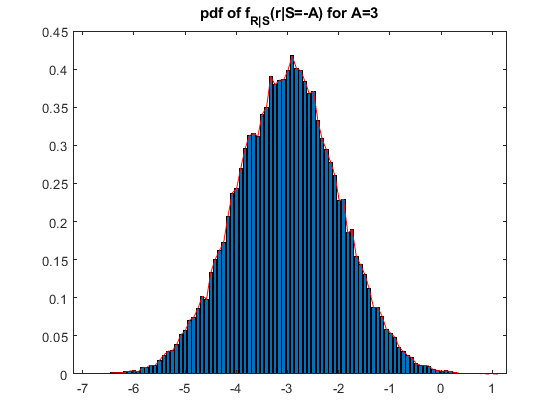


bin3 = 100;
width3 = (max(R_S2)-min(R_S2))/(bin3-1);
bins3 = (min(R_S2)-width3/2:width3:max(R_S2));

[y2,x2] = hist(R_S2,bins3);      %plotting the histogram
y2 = y2/((length(R_S2)-1)*width3);
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');                %plotting the pdf of f_{R|S}(r|S=-A)
title("pdf of f_{R|S}(r|S=-A) for A=3");

width = (max(R)-min(R))/(bin1-1);
bins = (min(R)-width/2:width:max(R));
%calculating E[R|S=A]
ER_SA=sum(width2.*x1.*y1)

ER_SA = 3.0039

%calculating E[R|S=-A]
ER_SA1=sum(width3.*x2.*y2)

ER_SA1 = -3.0032

%calculating E[R]
[y,x]=hist(R,bins);
y = y/(L*width);

ER=sum(width.*x.*y)

ER = -0.0011

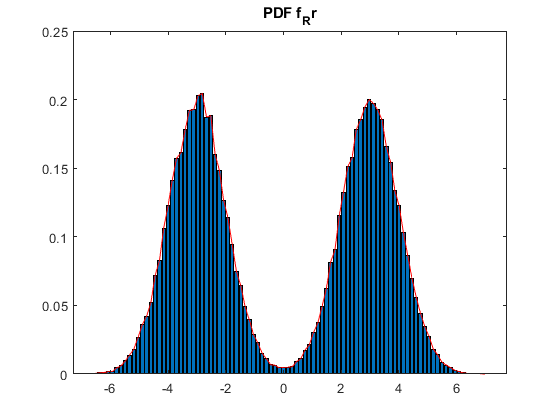

%plotting f_R(r)
figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("PDF f_{R}r");